clear;clc;

addpath(genpath('/Users/lyys/MyDocs/repos_from_github/gkaModelEye'))

sceneGeometry=createSceneGeometry()

sceneGeometry = struct with fields:
    cameraIntrinsic: [1×1 struct]
     cameraPosition: [1×1 struct]
     screenPosition: [1×1 struct]
                eye: [1×1 struct]
         refraction: [1×1 struct]
               meta: [1×1 struct]


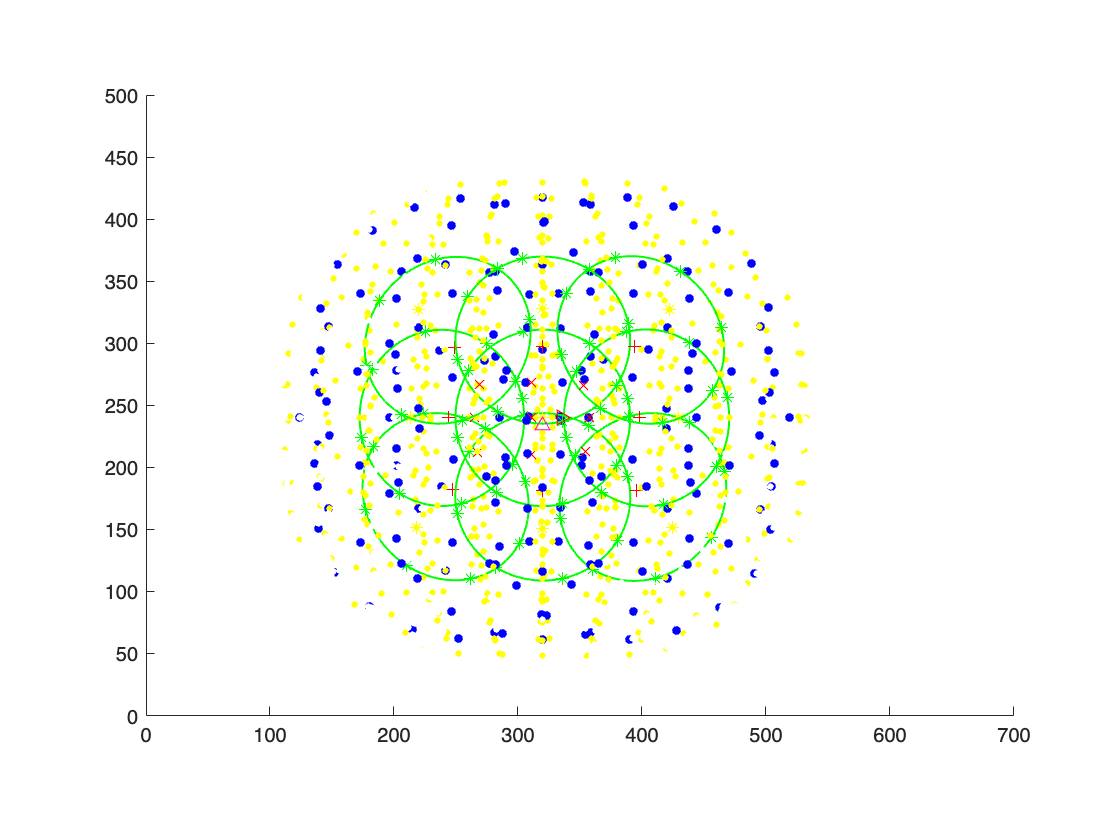


eyePoses=[-20 20 0 3; 0 20 0 3; 20 20 0 3; -20 0 0 3; 0 0 0 3; 20 0 0 3; -20 -20 0 3; 0 -20 0 3; 20 -20 0 3 ];


I = cell(1,9);
daspect([1 1 1])
% axis equal
for pp = 1:size(eyePoses,1)
    % Obtain the rendering of the model for this pose
    [figHandle, ~, renderedFrame] = renderEyePose(eyePoses(pp,:), sceneGeometry, 'newFigure',false);
    % close(figHandle)
    I{pp}=insertText(renderedFrame.cdata,[20 20],sprintf('[%d, %d, %d, %d]',eyePoses(pp,:)),'FontSize',30,'BoxColor','white');
end

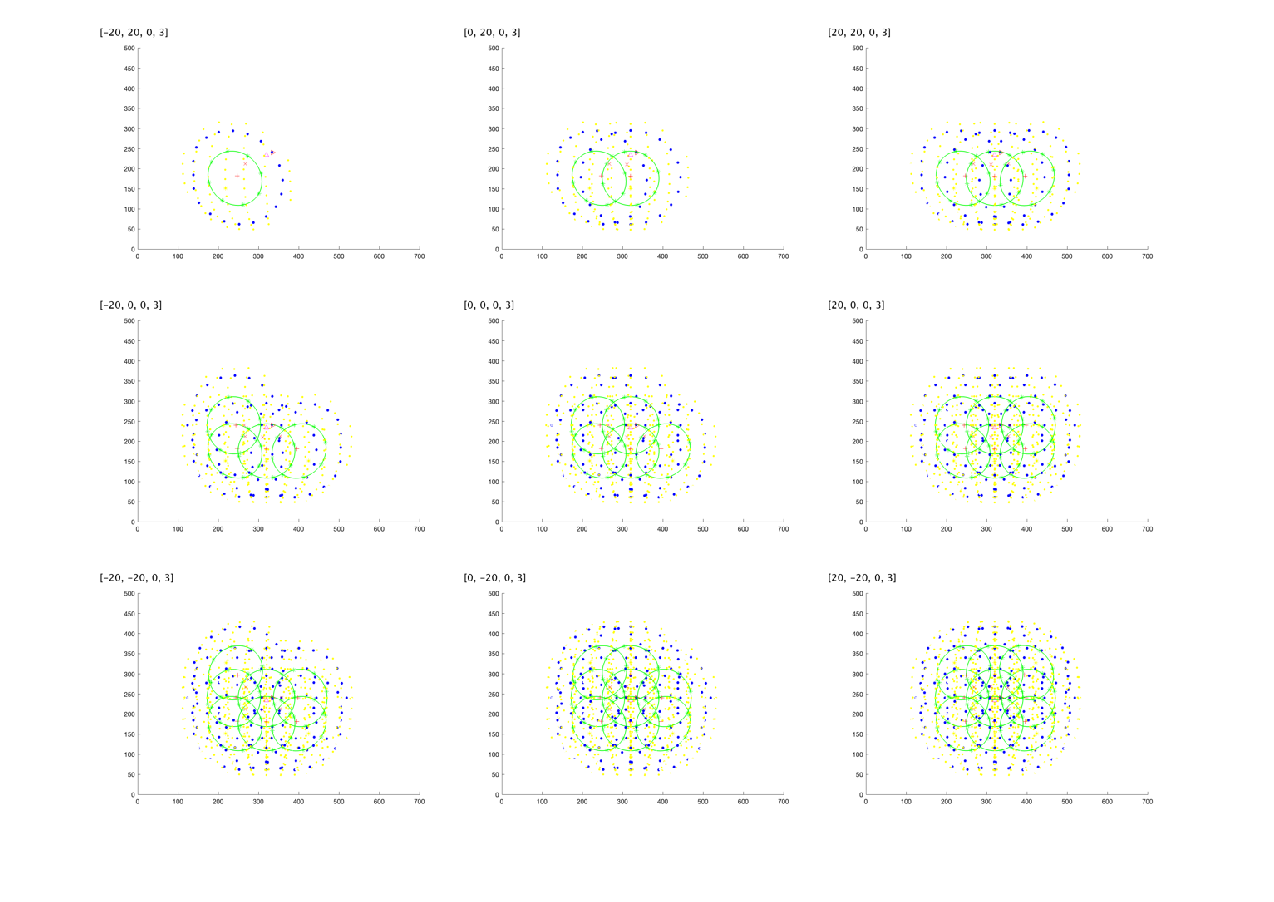

figure
montage(I)

## plotModelEyeSchematic

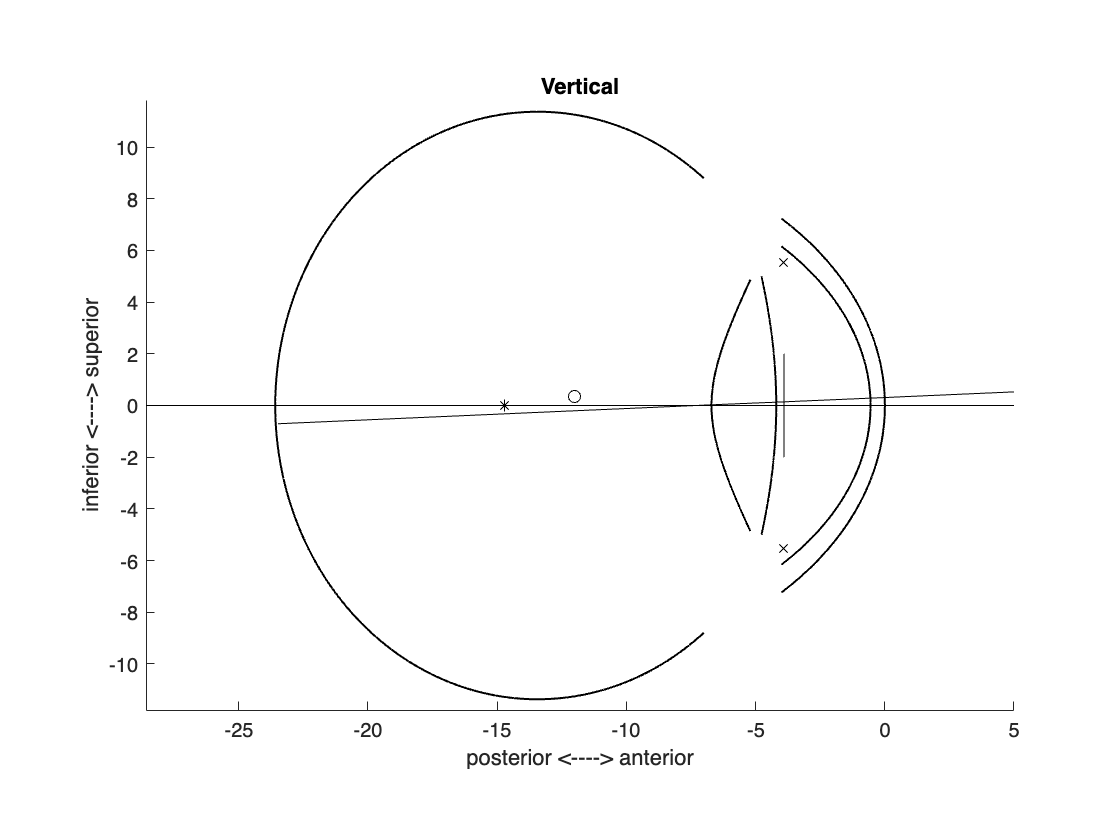

ans =   Figure (28) with properties:

      Number: 28
        Name: ''
       Color: [1 1 1]
    Position: [476 360 560 420]
       Units: 'pixels'

  Show all properties


sg1=createSceneGeometry('cameraGlintSourceRelative',[-14,0,0;14,0,0]');
figure
% sg1.eye.stop.center=-2;
plotModelEyeSchematic(sg1.eye, ...
    'plotIris',true, ...
    'plotStop',true, ...
    'plotRotationCenters',true, ...
    'plotVisualAxis',true, ...
    'view','sagittal')

## renderEyePose

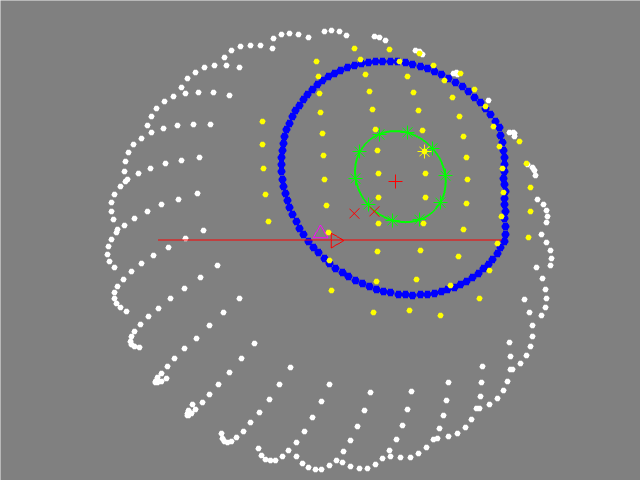

fig =   Figure (29) with properties:

      Number: 29
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [476 360 320 240]
       Units: 'pixels'

  Show all properties


plotobjs =   1×11 graphics array:

    Scatter                 Scatter                 Scatter                 Scatter                 Scatter                 Scatter                 ImplicitFunctionLine    Scatter                 Scatter                 Scatter                 Scatter             


frame = struct with fields:
       cdata: [480×640×3 uint8]
    colormap: []


pose1=[20,20,0,2];
% sg1.eye.iris.radius=5.5;
[fig,plotobjs,frame]=renderEyePose(pose1,sg1, ...
    'showAzimuthPlane',true, ...
    'nStopPerimPoints',10, ...
    'nIrisPerimPoints',100, ...
    'showPupilTextLabels',false)

% addCameraIcon(sg1)
% addScreenIcon(sg1)

iris=sg1.eye.iris

iris = struct with fields:
    thickness: 0
       center: [-3.9000 0 0]
       radius: 5.5500


stop=sg1.eye.stop

stop = struct with fields:
            center: [-3.9000 0 0]
       eccenParams: [-1.7582 4.7494 0.5747 0.0880]
    eccenFcnString: '@(x) (tanh((x+-1.758239).*4.749411)+0.574736)*0.087963'
            thetas: [0 1.3464]


[pupil_ellipse_params,glint_coord,image_points,~,~,~,point_labels]=projectModelEye(pose1,sg1,'fullEyeModelFlag',true)

pupil_ellipse_params = 1.0e+03 *

    0.4004    0.1766    6.4468    0.0004    0.0008


glint_coord =   354.5093  213.0444
  374.8349  211.9734


image_points =   401.2652  144.6645
  364.9478  153.3544
  358.7762  190.7837
  389.3990  219.4073
  425.7924  210.2285
  431.4895  172.9174
  395.3708  181.7921
  395.3708  181.7921
  335.2487  240.0000
  320.0000  233.5000


point_labels = 601×1 cell array
    {'stopPerimeter'      }
    {'stopPerimeter'      }
    {'stopPerimeter'      }
    {'stopPerimeter'      }
    {'stopPerimeter'      }
    {'stopPerimeter'      }
    {'stopCenter'         }
    {'irisActualCenter'   }
    {'aziRotationCenter'  }
    {'eleRotationCenter'  }
    {'vertex'             }
    {'fovea'              }
    {'opticDisc'          }
    {'medialCanthus'      }
    {'lateralCanthus'     }
    {'irisActualPerimeter'}
    {'irisActualPerimeter'}
    {'irisActualPerimeter'}
    {'irisActualPerimeter'}
    {'cornea'             }
    {'cornea'             }
    {'cornea'             }
    {'cornea'             }
    {'cornea'             }
    {'cornea'             }
    {'cornea'             }
    {'cornea'             }
    {'cornea'             }
    {'cornea'             }
    {'cornea'             }


pupil_ellipse_params

pupil_ellipse_params = 1.0e+03 *

    0.4004    0.1766    6.4468    0.0004    0.0008


pupil_ex=ellipse_transparent2ex(pupil_ellipse_params)

pupil_ex =   400.3719
  176.6258
   47.9282
   42.8155
    0.8066


pupil_im=ellipse_ex2im(pupil_ex)

pupil_im =     0.0000   -0.0000    0.0000   -0.0044   -0.0015    1.0000


poses={[20,20,0,2],[20,-20,0,2],[-20,-20,0,2],[-20,20,0,2]}

poses = 1×4 cell array
    {[20 20 0 2]}    {[20 -20 0 2]}    {[-20 -20 0 2]}    {[-20 20 0 2]}


out_ellipse=[];
for i=1:4
    elli_params_temp=projectModelEye(poses{i},sg1)
    out_ellipse(i,:)=ellipse_transparent2ex(elli_params_temp);
end

elli_params_temp = 1.0e+03 *

    0.4004    0.1766    6.4468    0.0004    0.0008


elli_params_temp = 1.0e+03 *

    0.3986    0.3024    6.4261    0.0005    0.0023


elli_params_temp = 1.0e+03 *

    0.2437    0.3022    6.3721    0.0004    0.0008


elli_params_temp = 1.0e+03 *

    0.2420    0.1769    6.3922    0.0005    0.0023


out_ellipse

out_ellipse =   400.3719  176.6258   47.9282   42.8155    0.8066
  398.6140  302.4283   47.9948   42.6192    2.3367
  243.7099  302.1607   47.6352   42.5800    0.8055
  241.9702  176.9047   47.8679   42.5065    2.3373


names={'cx','cy','a','b','theta'};
table2write=table(out_ellipse(:,1),out_ellipse(:,2),out_ellipse(:,3),out_ellipse(:,4),out_ellipse(:,5),'VariableNames',names)

table2write = 4×5 table
      cx        cy        a         b        theta 
    ______    ______    ______    ______    _______

    400.37    176.63    47.928    42.816    0.80659
    398.61    302.43    47.995    42.619     2.3367
    243.71    302.16    47.635     42.58    0.80553
    241.97     176.9    47.868    42.506     2.3373


write_path="/Users/lyys/MyDocs/repos/eyeball_translation/using_gkaModelEye/";
% writematrix(ellipse_transparent2ex(pupil_ellipse_params),write_path+"test.csv")
writetable(table2write,write_path+"table.csv")

count_surfaces(sg1.refraction.glint.opticalSystem)

ans = 2

strip_os(sg1.refraction.glint.opticalSystem)

ans =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    1.0000
    0.0050    0.0091    0.0093         0         0         0    0.0709         0         0   -0.0007   -1.0000   -3.9950    0.0049   -8.0000    8.0000   -8.0000    8.0000    1.0000   -1.0000


[os_glint,surface_labels,surface_colors,mag]=assembleOpticalSystem(modelEyeParameters(),'surfaceSetName','cameraToRetina')

os_glint =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    1.0000
    0.0050    0.0091    0.0093         0         0         0    0.0709         0         0   -0.0007   -1.0000   -3.9950    0.0049   -8.0000    8.0000   -8.0000    8.0000    1.0000    1.3301
    0.0050    0.0091    0.0093         0         0         0    0.0709         0         0    0.0000   -1.0000   -4.0000   -0.0000   -9.0000    9.0000   -9.0000    9.0000    1.0000    1.3714
    0.0053    0.0116    0.0116         0         0         0    0.0755         0         0    0.0815   -1.0000   -4.0000   -0.5500   -9.0000    9.0000   -9.0000    9.0000    1.0000    1.3315
   -0.0310    0.0084    0.0084         0         0         0    0.0459         0         0    0.9322   -1.0000   -5.2000   -4.1983   -5.0000    5.0000   -5.0000    5.0000    1.0000    1.3654
   -0.0310    0.0084    0.0084    

surface_labels = 49×1 cell array
    {'medium'                  }
    {'cornea.tearfilm'         }
    {'cornea.front'            }
    {'cornea.back'             }
    {'lens.front'              }
    {'lens.front.shell_n=1.367'}
    {'lens.front.shell_n=1.370'}
    {'lens.front.shell_n=1.373'}
    {'lens.front.shell_n=1.375'}
    {'lens.front.shell_n=1.378'}
    {'lens.front.shell_n=1.381'}
    {'lens.front.shell_n=1.384'}
    {'lens.front.shell_n=1.387'}
    {'lens.front.shell_n=1.390'}
    {'lens.front.shell_n=1.393'}
    {'lens.front.shell_n=1.395'}
    {'lens.front.shell_n=1.398'}
    {'lens.front.shell_n=1.401'}
    {'lens.front.shell_n=1.404'}
    {'lens.front.shell_n=1.407'}
    {'lens.front.shell_n=1.410'}
    {'lens.front.shell_n=1.412'}
    {'lens.front.shell_n=1.415'}
    {'lens.front.shell_n=1.418'}
    {'lens.front.shell_n=1.421'}
    {'lens.front.shell_n=1.424'}
    {'lens.back.shell_n=1.424' }
    {'lens.back.shell_n=1.421' }
    {'lens.back.shell_n=1.418' }
    {'lens

surface_colors = 49×1 cell array
    {[                NaN NaN NaN]}
    {[       0.5000 0.5000 0.7500]}
    {[       0.5000 0.5000 0.7500]}
    {[       0.5000 0.5000 0.7500]}
    {[0.7500 0.7500 0.7500 0.7500]}
    {[0.7500 0.7619 0.7500 0.1000]}
    {[0.7500 0.7738 0.7500 0.1000]}
    {[0.7500 0.7857 0.7500 0.1000]}
    {[0.7500 0.7976 0.7500 0.1000]}
    {[0.7500 0.8095 0.7500 0.1000]}
    {[0.7500 0.8214 0.7500 0.1000]}
    {[0.7500 0.8333 0.7500 0.1000]}
    {[0.7500 0.8452 0.7500 0.1000]}
    {[0.7500 0.8571 0.7500 0.1000]}
    {[0.7500 0.8690 0.7500 0.1000]}
    {[0.7500 0.8810 0.7500 0.1000]}


mag = struct with no fields.


[pupil_ellipse_params_lyy,glint_coord_lyy,image_points_lyy,~,~,~,point_labels_lyy]=projectModelEye_lyy(poses{1},sg1,'fullEyeModelFlag',false)

pupil_ellipse_params_lyy = 1.0e+03 *

    0.4004    0.1766    6.4468    0.0004    0.0008


glint_coord_lyy =   354.5093  213.0444
  374.8349  211.9734
  437.4514  146.6248
  418.1469  150.0395


image_points_lyy =   401.2652  144.6645
  364.9478  153.3544
  358.7762  190.7837
  389.3990  219.4073
  425.7924  210.2285
  431.4895  172.9174
  407.3695  132.6906
  364.8166  144.5382
  358.0251  188.0214
  392.4833  220.3070


point_labels_lyy = 16×1 cell array
    {'stopPerimeter' }
    {'stopPerimeter' }
    {'stopPerimeter' }
    {'stopPerimeter' }
    {'stopPerimeter' }
    {'stopPerimeter' }
    {'pupilPerimeter'}
    {'pupilPerimeter'}
    {'pupilPerimeter'}
    {'pupilPerimeter'}
    {'pupilPerimeter'}
    {'pupilPerimeter'}
    {'glint_01'      }
    {'glint_02'      }
    {'glint_4th_01'  }
    {'glint_4th_02'  }


wrapTo360(-2360)

ans = 160

a=-390

a = -390

function out=func1(varargin)
    out=varargin{:}
end
%%

function striped=strip_os(opticalSystem)
    striped=opticalSystem(sum(isnan(opticalSystem),2)~=size(opticalSystem,2),:);
end

function num=count_surfaces(opticalSystem)
    num=size(strip_os(opticalSystem),1);
end

function lon = wrapTo360(lon)
positiveInput = (lon > 0);
lon = mod(lon, 360);
lon((lon == 0) & positiveInput) = 360;
end
